type = 'K';
sim_num = 1e5;     % The number of scenarios to simulate.
N = 16;             % Number of pulses per CPI.
K = 2*N;           % Number of secondary data samples used for parameter estimation.
PFA_max = 1e-3    % Desired probability of false alarm.

PFA_max = 1.0000e-03

PFA_min = 10.^(-3.02)

PFA_min = 9.5499e-04

threshhold = 0.6063

count = 7

PFA = 9.8000e-04

threshhold = 0.5755

PFA = 0.0011

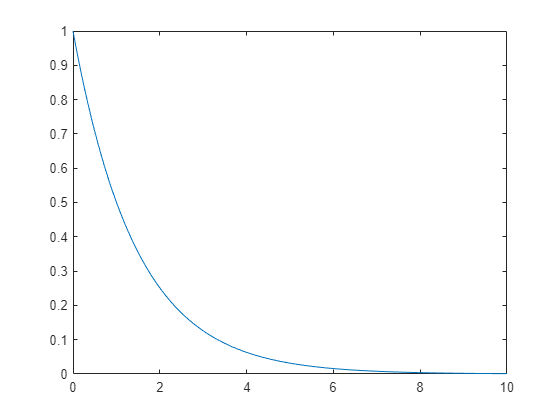

z = 6

delta = 1

z = 7

delta = 1

i = 2

z = 7

a = 0.5;

TH_init = .5;
delta = .1;

[threshold,count,PFA] = glrt_TH_optimizer(TH_init, delta, type, a, sim_num, N, K, PFA_max, PFA_min) 

function [PFA] = glrt_PFA(type, a, sim_num, N, K, P_fa, threshhold)
alg = 'glrt';   % This sets the type of adaptive detector that will be applied.
PRI = 1e-8;     % Pulse repetition interval.
f_d = 2e7;      % Doppler frequency.
i = 1:N;        % Pulse number.
rho = 0.9;      % The one-lag correlation coefficient.
b = 1;
p = exp(-1j*2*pi*i*f_d*PRI); 
[d] = ClutterSimNG(type,sim_num+K,K,N,rho,a,b);
FA=0;
for zz = 1:length(d)-K
    % Estimate the clutter mean and covariance
    mu_est = sum(d(zz+1:zz+K,:),'all')/(K*N);                                      % Estimated clutter mean
    cov_est = zeros(K,N,N);
    for kk = 1:K
        cov_est(kk,:,:) = (d(zz+kk,:)'-mu_est)*(d(zz+kk,:)-mu_est);
    end
    M_est = squeeze(sum(cov_est,1))/K;                                      % Estimated clutter covariance
    S = K*M_est;                                                            % Parameter S = KM
    clear cov_est;

    [detection_glrt,eta_glrt,eta_0_glrt] = detector('glrt',d(zz,:),p,S,P_fa,K,N);
    if (eta_glrt> threshhold)
        FA = FA+1;
    end
end
PFA = FA/sim_num; 
end

function [threshold,count,PFA] = glrt_TH_optimizer(TH_init, delta, type, a, sim_num, N, K, PFA_max, PFA_min)
threshold = TH_init;
count=1;
flip=0;
PFA = glrt_PFA(type, a, sim_num, N, K, PFA_max, threshold);
while or((PFA>PFA_max),(PFA<PFA_min))
    if (PFA>PFA_max)
        threshold = threshold+delta;
        PFA = glrt_PFA(type, a, sim_num, N, K, PFA_max, threshold);
        if (PFA<PFA_min)
            flip = 1;
        end
    else
        threshold = threshold-delta;
        PFA = glrt_PFA(type, a, sim_num, N, K, PFA_max, threshold);
        if (PFA<PFA_min)
            flip = 1;
        end
    end
    if flip==1
        delta=delta/2;
    end
    count=count+1;
end
end